# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 2022-06-06 16:33:57

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 9);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ["\t", ","];

% Specify column names and types
opts.VariableNames = ["Freq", "abs_me_v", "arg_me_v", "abs_me_x", "arg_me_x", "abs_ac_v", "arg_ac_v", "abs_ac_x", "arg_ac_x"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, [ "abs_me_v", "arg_me_v", "abs_me_x", "arg_me_x", "abs_ac_v", "arg_ac_v", "abs_ac_x", "arg_ac_x"], "TrimNonNumeric", true);
opts = setvaropts(opts, [ "abs_me_v", "arg_me_v", "abs_me_x", "arg_me_x", "abs_ac_v", "arg_ac_v", "abs_ac_x", "arg_ac_x"], "ThousandsSeparator", ",");

% Import the data
tbl = readtable("ME_Diaphragm_3DOF_linear.txt", opts);

## Convert to output type

Freq = tbl.Freq;
abs_me_v = 10.^(tbl.abs_me_v/20);
abs_me_x = 10.^(tbl.abs_me_x/20);
abs_ac_v = 10.^(tbl.abs_ac_v/20);
abs_ac_x = 10.^(tbl.abs_ac_x/20);
arg_me_v = tbl.arg_me_v;
arg_me_x = tbl.arg_me_x;
arg_ac_v = tbl.arg_ac_v;
arg_ac_x = tbl.arg_ac_x;

## Clear temporary variables

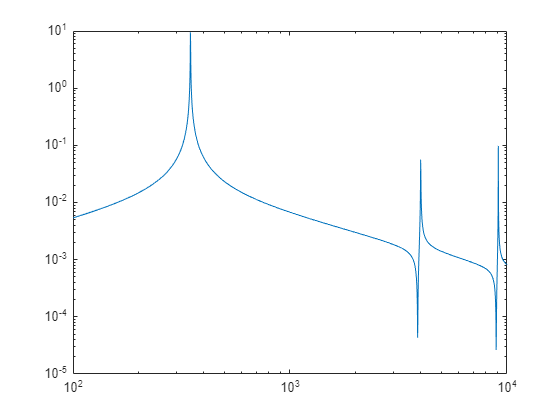

clear opts tbl

loglog(Freq,abs_me_v);

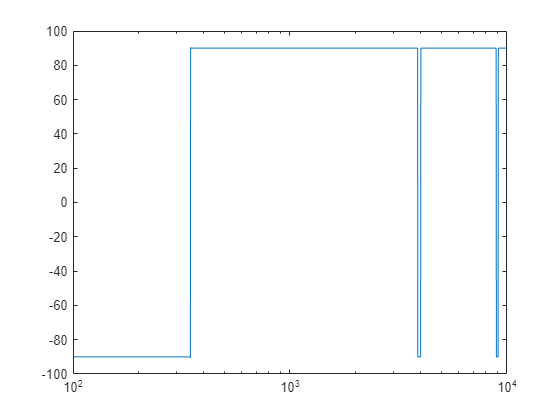

semilogx(Freq,arg_me_v);

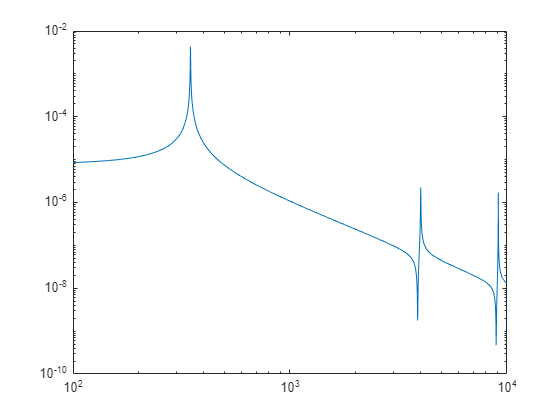

loglog(Freq,abs_me_x);

semilogx(Freq,arg_me_x);

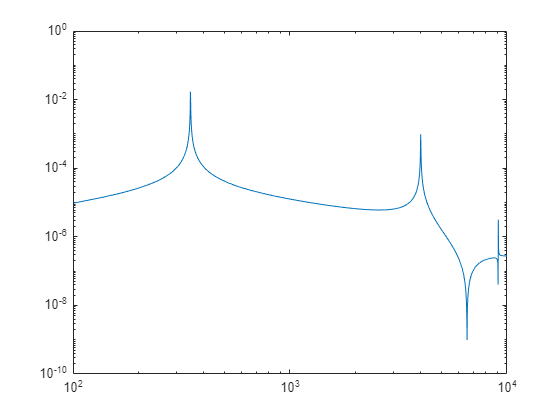


loglog(Freq,abs_ac_v);

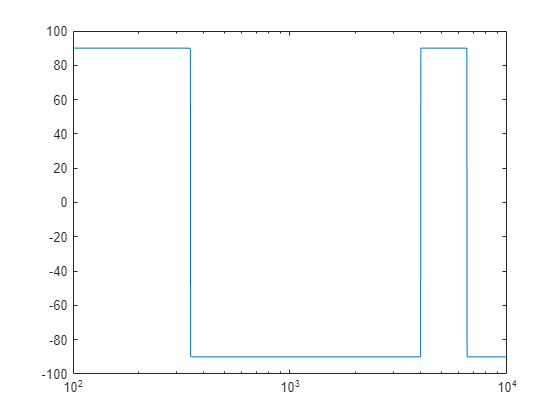

semilogx(Freq,arg_ac_v);

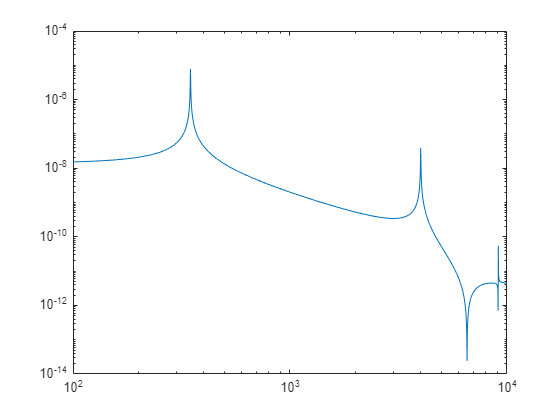

loglog(Freq,abs_ac_x);

semilogx(Freq,arg_ac_x);

hold off

D = [Freq, abs_me_v, arg_me_v, abs_me_x, arg_me_x, abs_ac_v, arg_ac_v, abs_ac_x, arg_ac_x];
save 'ME_Diaphragm_3DOF_linear_.txt' D -ascii
clear D
